# segmentaionUsingRFOVEEllipsesMethod

RFOVE - Cell Segmentation-Costas Panagiotakis

[1] C. Panagiotakis and A.A. Argyros, "Region-based Fitting of Overlapping Ellipses and its Application to Cells Segmentation", Image and Vision Computing, Elsevier, vol. 93, pp. 103810, 2020.

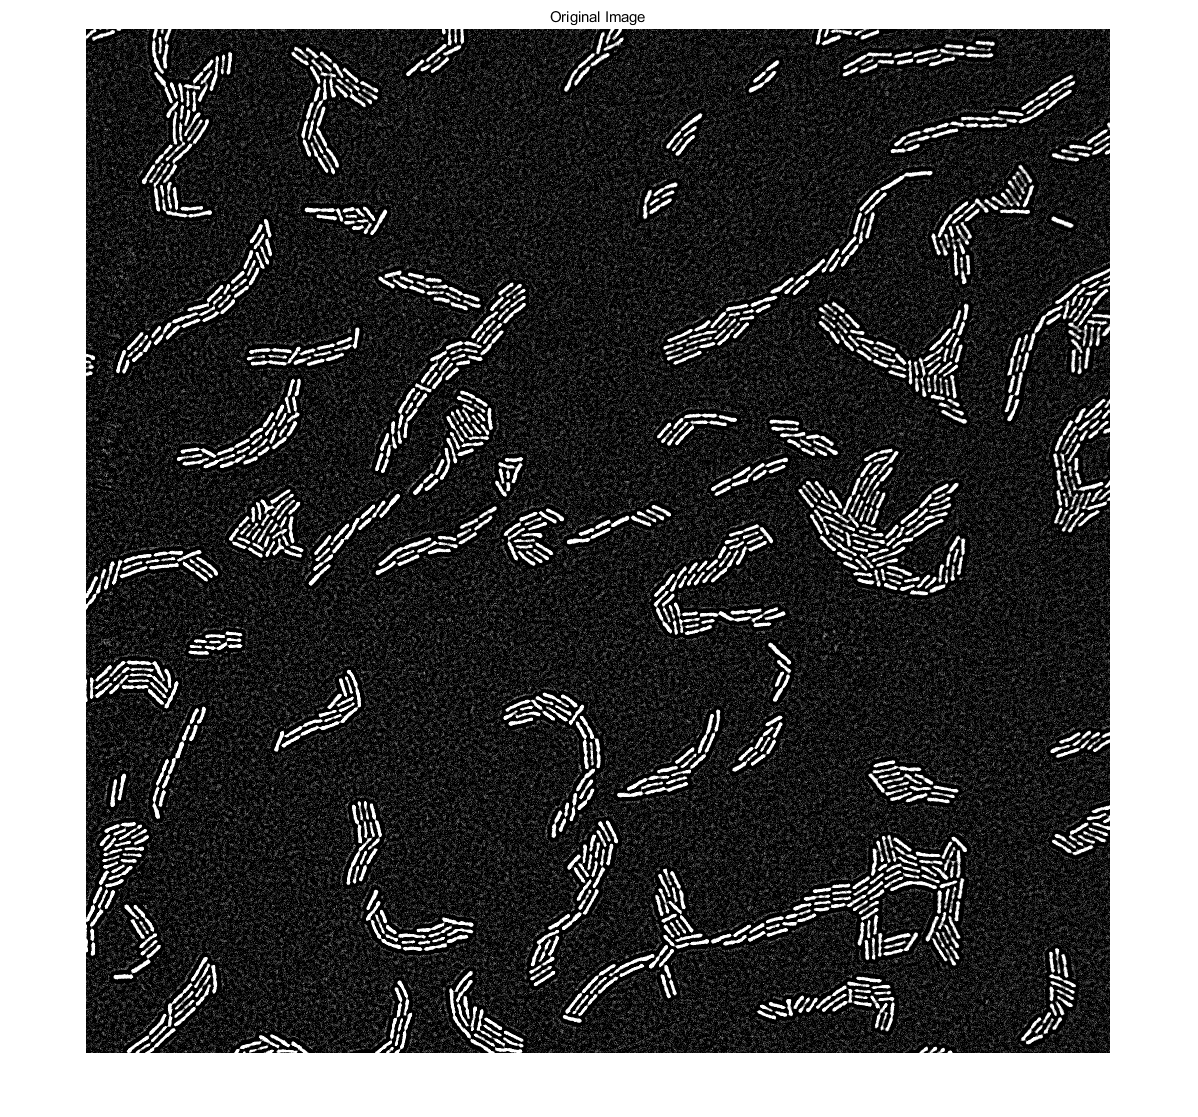

image=import_tiff_stack('E:\2019-12-26 PAO1_deltpslpelfliC_IP32_100x ys\field0004\BF\imageBF04000.tif');
I=image;
se = strel('disk',2);
Io = imopen(I,se);
imshow(I), title('Original Image')

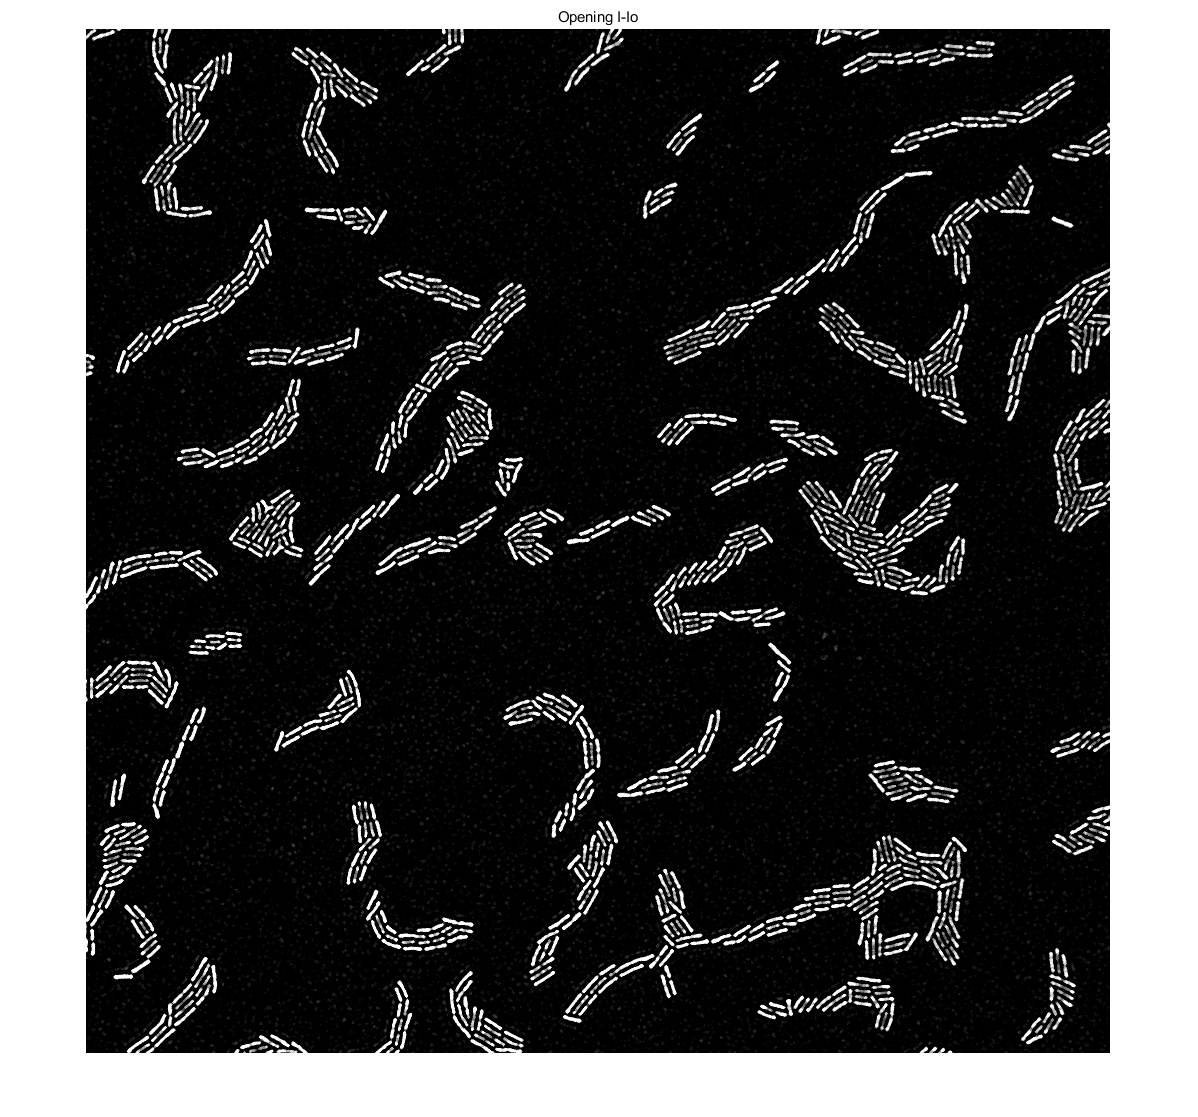

imshow(Io),title('Opening I-Io')

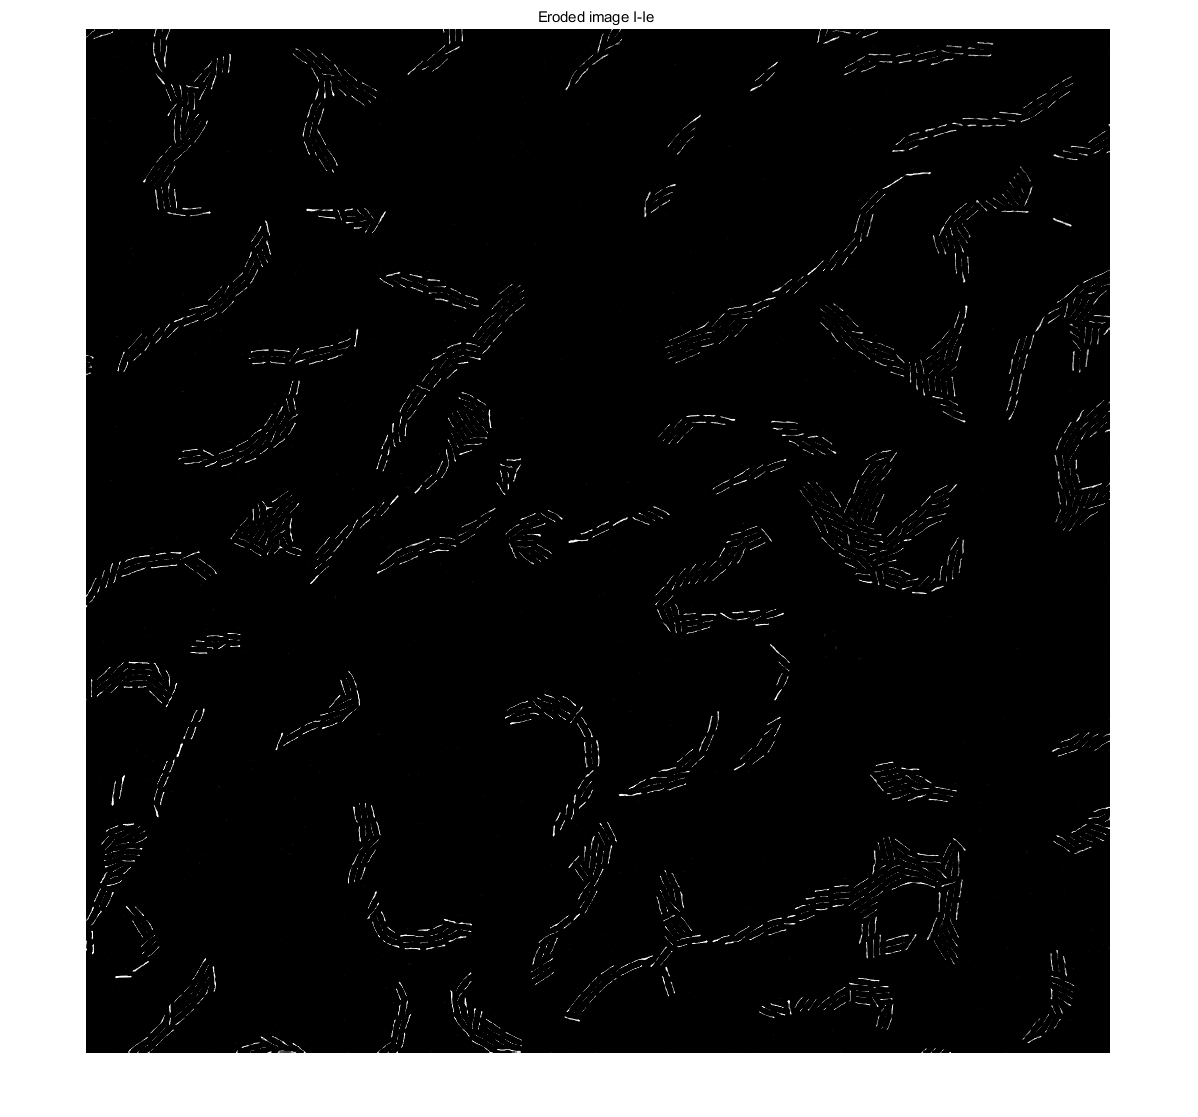


Ie = imerode(Io,strel('disk',3));
imshow(Ie), title('Eroded image I-Ie ')

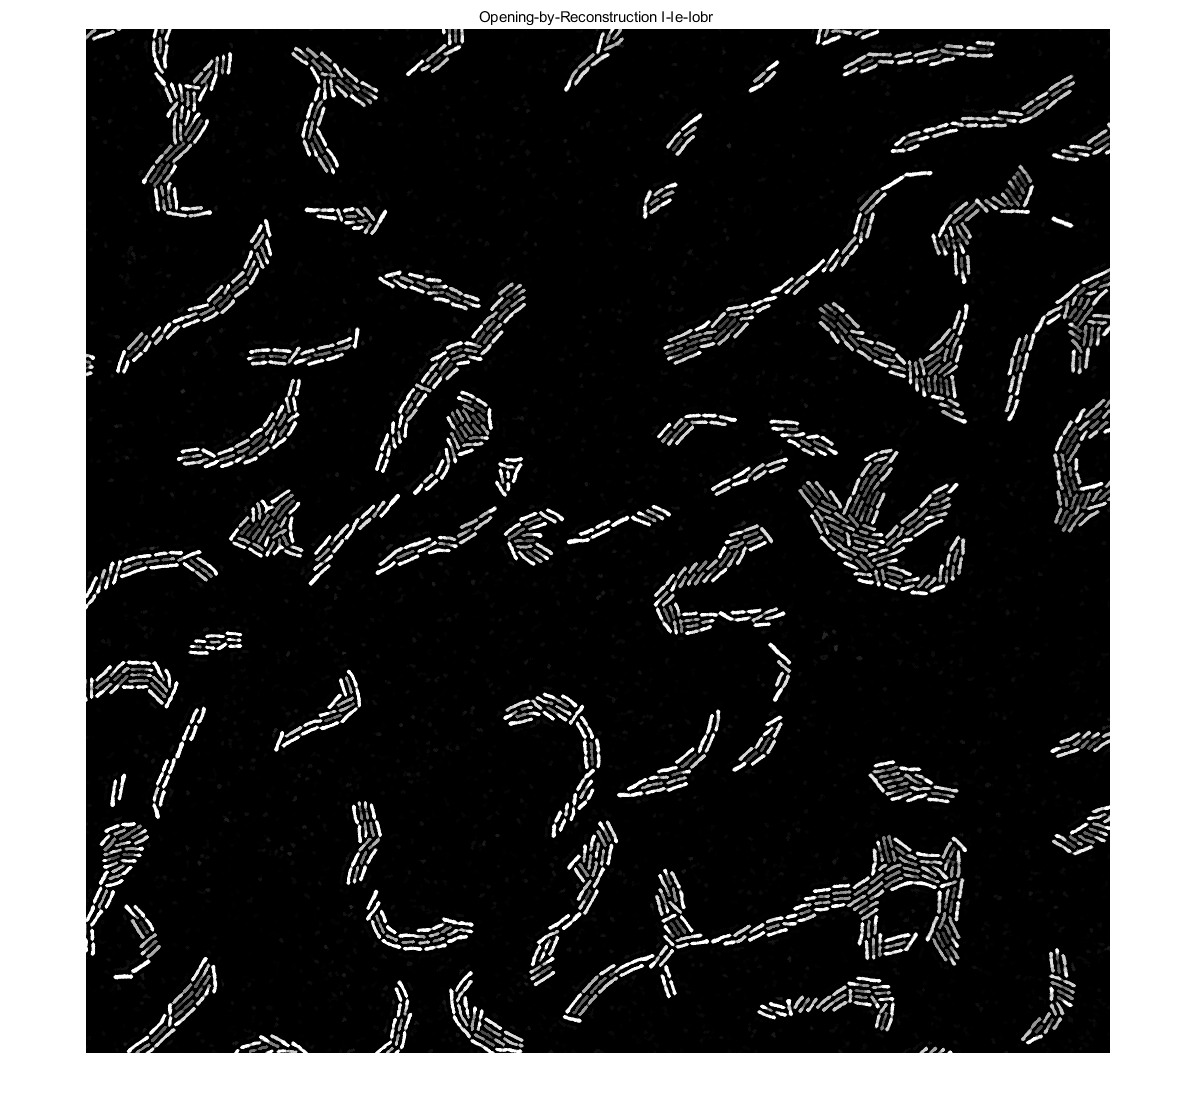

Iobr = imreconstruct(Ie,Io);
imshow(Iobr),title('Opening-by-Reconstruction I-Ie-Iobr ')

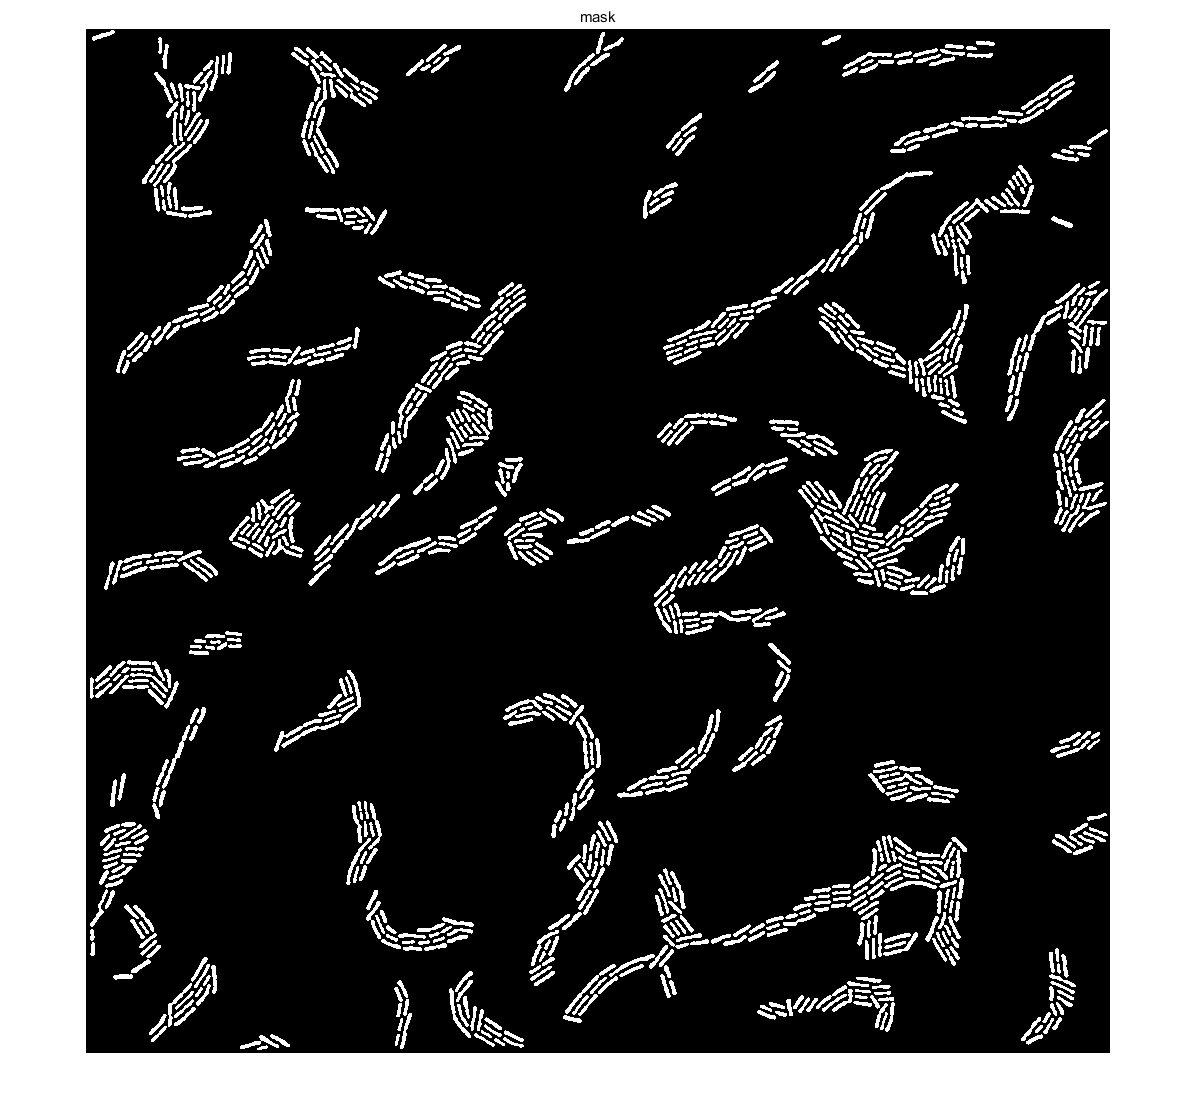


[bw,~] = myImageProcessing_cBFys(Iobr,'w');
% parameter
% % grayThresh=40;
% % areaThreshold=100;  % proper 60, overlap 60+40
% % maxIntensity=45;
imshow(bw),title('mask')

selectedBigRegions

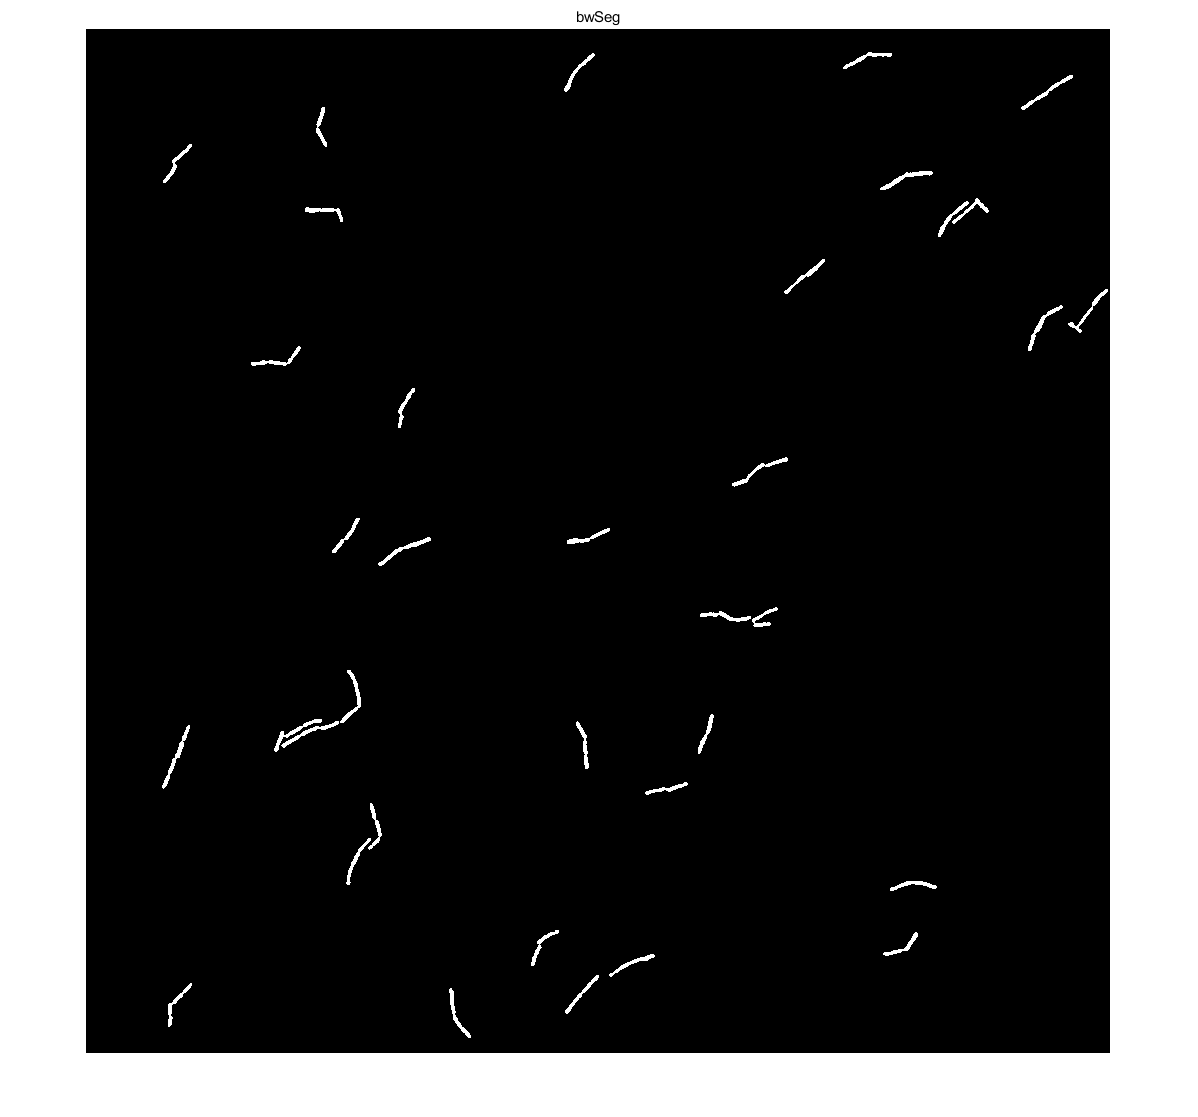

bwSeg = zeros(size(bw,1),size(bw,2));

stats = regionprops(bw,'PixelIdxList');
pixelNum = zeros(2,numel(stats));
for j=1:numel(stats)
    pixelNum(1,j)=j;
    pixelNum(2,j)=numel(stats(j).PixelIdxList);
end
templogic=(pixelNum(2,:)>=600);
if sum(templogic)>0
    stats=stats(templogic);
    for k=1:numel(stats)
        bwSeg(stats(k).PixelIdxList)=1;
        tempImage=false(size(image,1),size(image,2));
    end
end

imshow (bwSeg),title ('bwSeg')

bwSeg1=imerode(bwSeg,ones(4));
bwSeg1 = bwareaopen(bwSeg1, 2);
skel = bwmorph(bwSeg1,'skel',Inf);
E = bwmorph(skel, 'endpoints');
skel=skel&(~E); %删除endpoint 要不膨胀会连在一起
E = bwmorph(skel, 'endpoints');
skel=skel&(~E);


testRFOVEMethod

CC = bwconncomp(bwSeg, 8);
L = labelmatrix(CC);
% [ IClustTotal,totEll,INITSEG] = runMainAlgoTestYs(Iobr,CC,L); % 效果不好
% 可能对圆形的分割会好些
% imshow(label2rgb(IClustTotal))
